Load Data

all_channels = load("vibro_test.csv");
used_electrodes = all_channels(:, 1:5);
sorted_electrodes = zeros(size(used_electrodes));

sorted_electrodes(:, 1) = used_electrodes(:, 4);
sorted_electrodes(:, 2) = used_electrodes(:, 5);
sorted_electrodes(:, 3) = used_electrodes(:, 3);
sorted_electrodes(:, 4) = used_electrodes(:, 1);
sorted_electrodes(:, 5) = used_electrodes(:, 2);

Fs = 250;

Filter

average = mean(sorted_electrodes);
for i=1:5
    sorted_electrodes(:, i) = sorted_electrodes(:, i) - average(i);
end

filtered_data = bandstop(sorted_electrodes, [49, 51], Fs);
filtered_data = bandpass(filtered_data, [10, 60], Fs);
filtered_data = filtered_data';

Plot data and FFT

first_sample = Fs*30;
last_sample = first_sample + Fs * 30;
N = last_sample - first_sample;
t = (first_sample:last_sample) / Fs;
window_size = 4 * Fs;
most_left = []


most_left =

     []



most_right = []


most_right =

     []



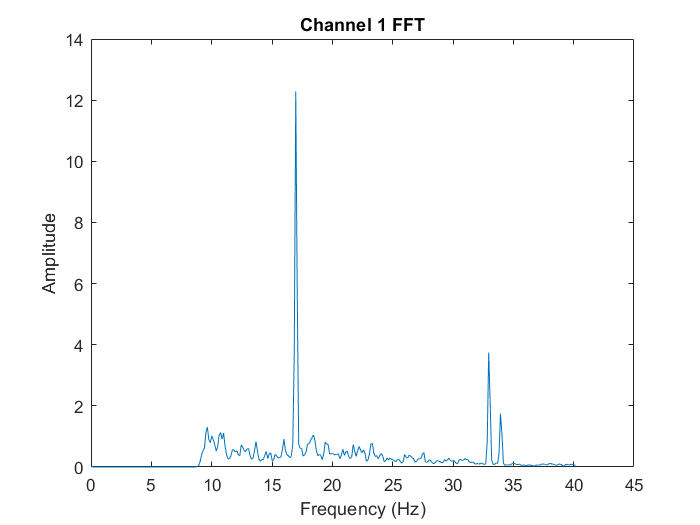

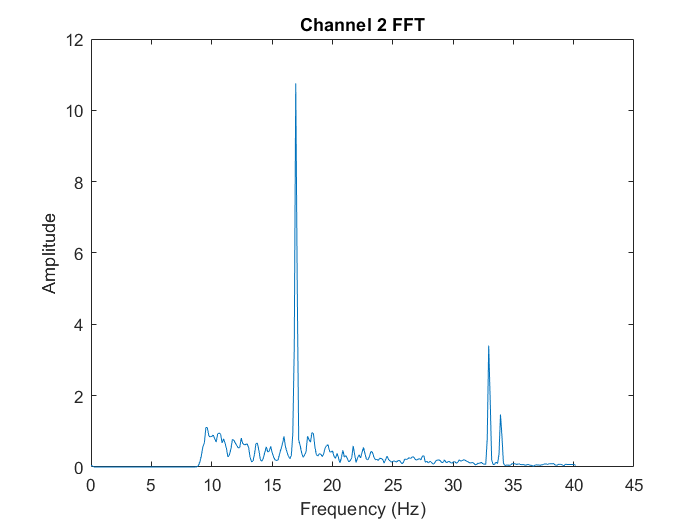

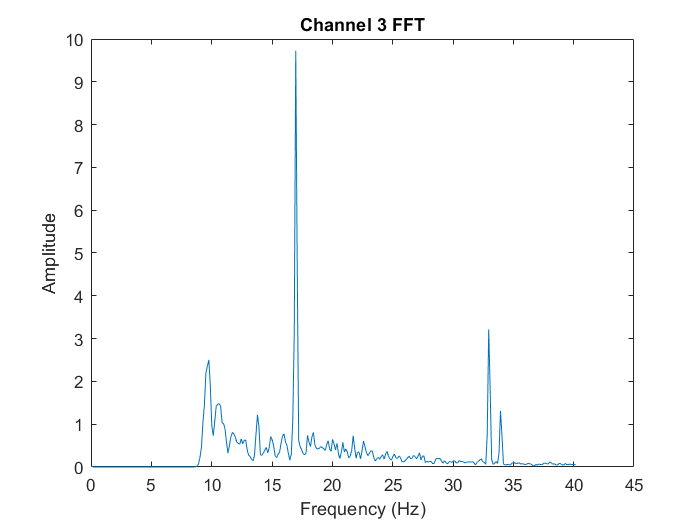

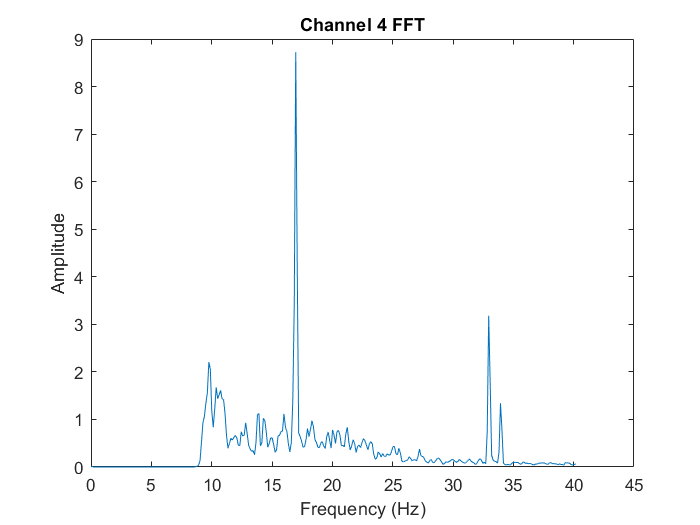

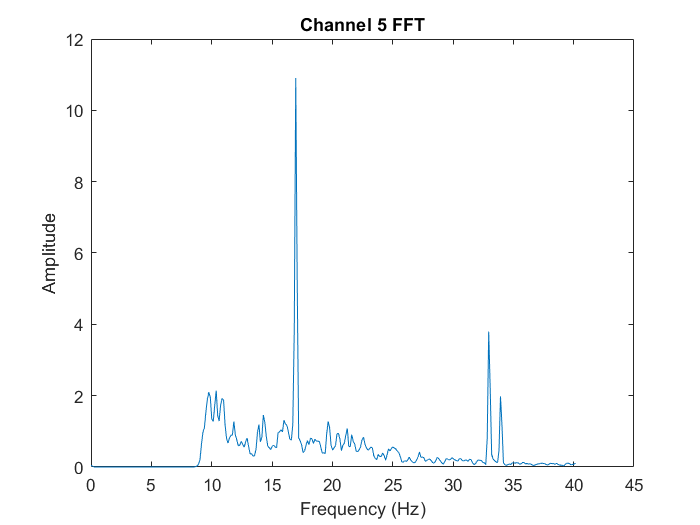

for i=1:5
    current_data = filtered_data(i, first_sample:last_sample);
    %Y = 1/N * abs(fft(current_data));
    %Y = Y(1:N/2);
    %freq = (0:N/2 - 1) * Fs/N;
    [power, freq] = pwelch(current_data, [], [], [], Fs);
    
    if i==1
        most_left = power;
    end
    
    if i==5
        most_right = power;
    end
    
    figure;
    
    plot(freq(1:330), power(1:330));
    title("Channel " + i + " FFT")
    xlabel("Frequency (Hz)")
    ylabel("Amplitude")
end

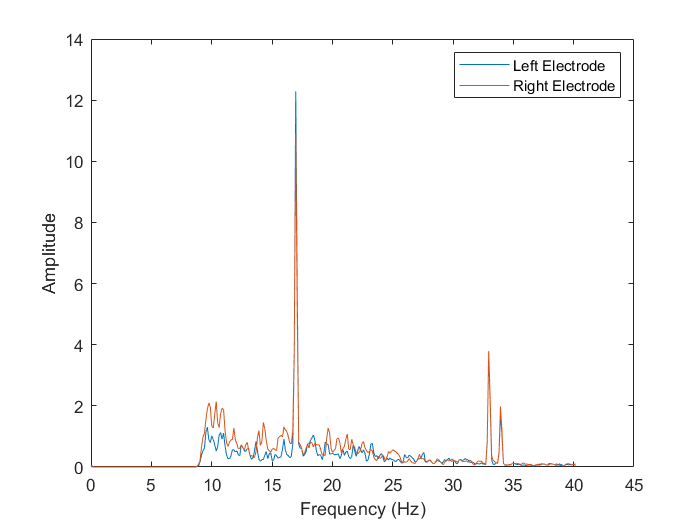


figure;
plot(freq(1:330), most_left(1:330))
hold on;
plot(freq(1:330), most_right(1:330))
xlabel("Frequency (Hz)")
ylabel("Amplitude")
legend("Left Electrode", "Right Electrode")

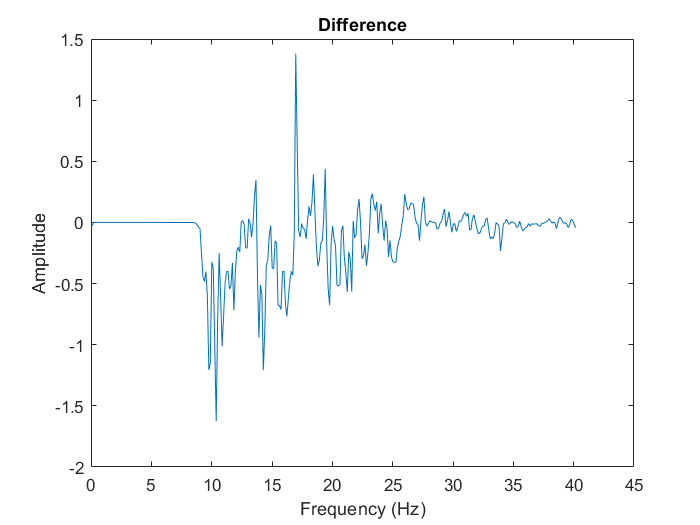

diff = most_left - most_right;
figure;
plot(freq(1:330), diff(1:330))
title("Difference")
xlabel("Frequency (Hz)")
ylabel("Amplitude")